**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

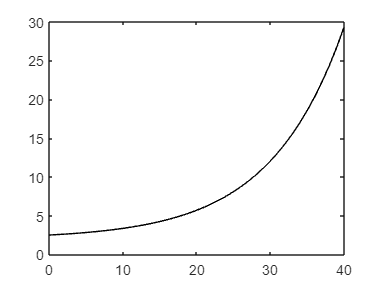

xx = 0 : 1 : 40;
yy = 0.5 .* exp(0.1 .* xx) + 2;

plot(xx,yy,'k-')

**2) If we know this function and we want to find out what is y when x = 22?**

xtest = 22;
ytrue = 0.5 .* exp(0.1 .* xtest) + 2

ytrue = 6.5125

 **3) Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation to predict the y value when x = 22**

x = linspace(0,40,2) ;
y = 0.5 .* exp(0.1*x) + 2 ;
yy1 = Newtint(x,y,xx)

yy1 =     2.5000    3.1700    3.8400    4.5099    5.1799    5.8499    6.5199    7.1898    7.8598    8.5298    9.1998    9.8697   10.5397   11.2097   11.8797   12.5497   13.2196   13.8896   14.5596   15.2296   15.8995   16.5695   17.2395   17.9095   18.5794   19.2494   19.9194   20.5894   21.2594   21.9293   22.5993   23.2693   23.9393   24.6092   25.2792   25.9492   26.6192   27.2891   27.9591   28.6291   29.2991


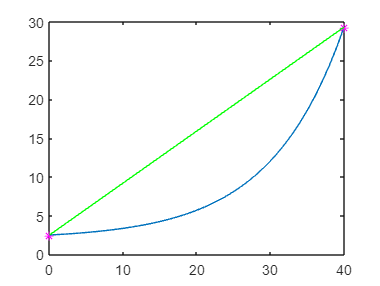


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,"-g")
hold off


xtest = 22;
y_pred = Newtint(x,y,xtest)

y_pred = 17.2395

**4) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use quadratic interpolation to predict the y value when x = 22**



x = linspace(0,40,3) ;
y = 0.5 .* exp(0.1*x) + 2 ;
yy3 = Newtint(x,y,xx)

yy3 =     2.5000    2.1750    1.9010    1.6780    1.5061    1.3852    1.3153    1.2964    1.3286    1.4118    1.5460    1.7313    1.9675    2.2548    2.5931    2.9825    3.4228    3.9142    4.4566    5.0501    5.6945    6.3900    7.1365    7.9341    8.7826    9.6822   10.6328   11.6345   12.6871   13.7908   14.9455   16.1513   17.4081   18.7158   20.0747   21.4845   22.9454   24.4573   26.0202   27.6341   29.2991


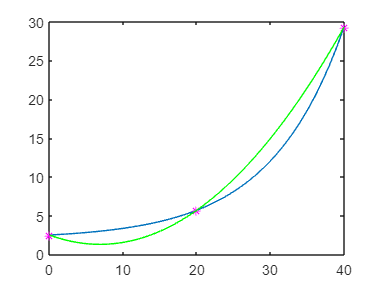


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy3,"-g")
hold off


xtest = 22;
y_pred = Newtint(x,y,xtest)

y_pred = 7.1365

**5) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use cubic interpolation to predict the y value when x = 22**


x = linspace(0,40,4) ;
y = 0.5 .* exp(0.1*x) + 2 ;
yy4 = Newtint(x,y,xx)

yy4 =     2.5000    2.7120    2.8893    3.0364    3.1580    3.2585    3.3427    3.4151    3.4803    3.5430    3.6076    3.6789    3.7614    3.8597    3.9785    4.1222    4.2956    4.5032    4.7496    5.0394    5.3773    5.7677    6.2153    6.7248    7.3007    7.9475    8.6700    9.4727   10.3602   11.3371   12.4080   13.5775   14.8502   16.2307   17.7237   19.3336   21.0651   22.9228   24.9113   27.0352   29.2991


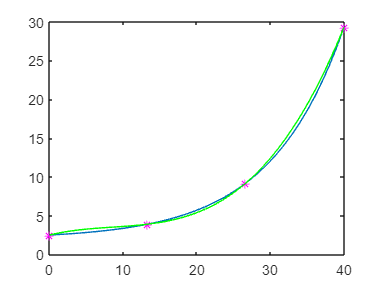


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy4,"-g")
hold off


xtest = 22;
y_pred = Newtint(x,y,xtest)

y_pred = 6.2153